# Example 5-1

# 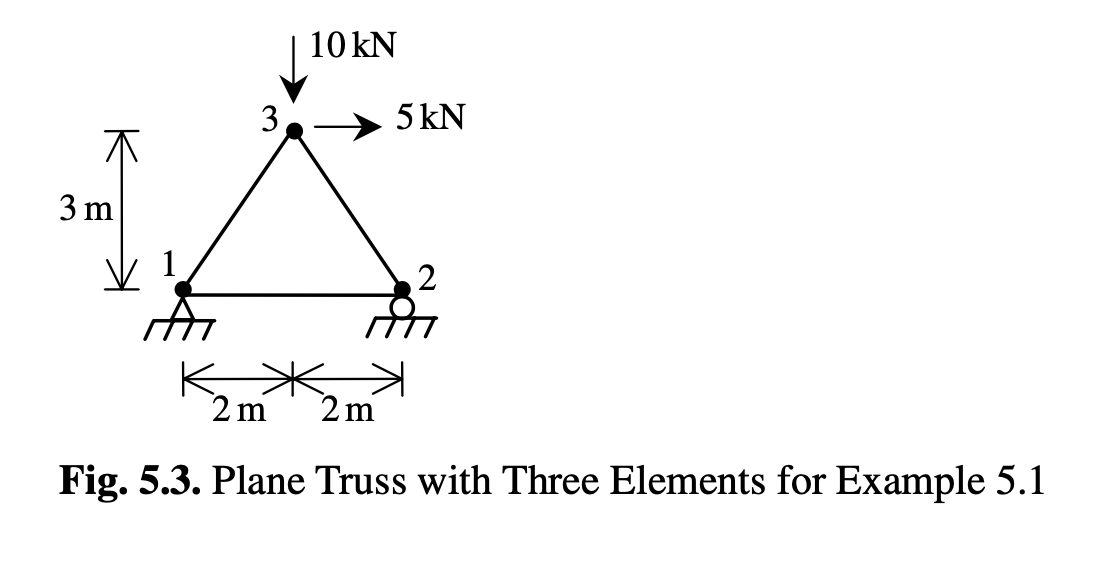

## Step 1: Descretizing the domain

ElemConnec = [1, 2; 1, 3; 2, 3]

ElemConnec =      1     2
     1     3
     2     3


## Step 2: Writing the Element Striffness Matrices

E = 2.1e8;
A = 1e-4;
L1 = 4;
L2 = PlaneTrussElementLength(0, 0, 2, 3);
L3 = PlaneTrussElementLength(0, 0, -2, 3);

theta2 = atan(3/2)*180/pi;
theta3 = 180 - theta2;

k1 = PlaneTrussElementStiffness(E, A, L1, 0)

k1 =         5250           0       -5250           0
           0           0           0           0
       -5250           0        5250           0
           0           0           0           0


k2 = PlaneTrussElementStiffness(E, A, L2, theta2)

k2 = 	1.0e+03 *

    1.7921    2.6882   -1.7921   -2.6882
    2.6882    4.0322   -2.6882   -4.0322
   -1.7921   -2.6882    1.7921    2.6882
   -2.6882   -4.0322    2.6882    4.0322


k3 = PlaneTrussElementStiffness(E, A, L3, theta3)

k3 = 	1.0e+03 *

    1.7921   -2.6882   -1.7921    2.6882
   -2.6882    4.0322    2.6882   -4.0322
   -1.7921    2.6882    1.7921   -2.6882
    2.6882   -4.0322   -2.6882    4.0322


## Step 3: Assembling the Global Stiffness Matrix

K = zeros(6);
K = PlaneTrussAssemble(K, k1, 1, 2);
K = PlaneTrussAssemble(K, k2, 1, 3);
K = PlaneTrussAssemble(K, k3, 2, 3)

K = 	1.0e+03 *

    7.0421    2.6882   -5.2500         0   -1.7921   -2.6882
    2.6882    4.0322         0         0   -2.6882   -4.0322
   -5.2500         0    7.0421   -2.6882   -1.7921    2.6882
         0         0   -2.6882    4.0322    2.6882   -4.0322
   -1.7921   -2.6882   -1.7921    2.6882    3.5842    0.0000
   -2.6882   -4.0322    2.6882   -4.0322    0.0000    8.0645


## Step 4: Applying the Boundary Conditions

% U1x = U1y = U2y = 0; F2x = 0; F3x = 5, F3y = -10

## Step 5: Solving the Equations

k = [K(3, 3) K(3, 5:6); K(5:6, 3) K(5:6, 5:6)]

k = 	1.0e+03 *

    7.0421   -1.7921    2.6882
   -1.7921    3.5842    0.0000
    2.6882    0.0000    8.0645


f = [0; 5; -10]

f =      0
     5
   -10


u = k\f

u =     0.0011
    0.0020
   -0.0016


## Step 6: Post Processing

U = [0; 0; u(1); 0; u(2:3)]

U =          0
         0
    0.0011
         0
    0.0020
   -0.0016


F = K*U

F =    -5.0000
    1.2500
   -0.0000
    8.7500
    5.0000
  -10.0000



u1 = [U(1); U(2); U(3); U(4)]

u1 =          0
         0
    0.0011
         0


u2 = [U(1); U(2); U(5); U(6)]

u2 =          0
         0
    0.0020
   -0.0016


u3 = [U(3); U(4); U(5); U(6)]

u3 =     0.0011
         0
    0.0020
   -0.0016



sigma1 = PlaneTrussElementStress(E, L1, 0, u1)

sigma1 = 5.8333e+04

sigma2 = PlaneTrussElementStress(E, L2, theta2, u2)

sigma2 = -1.5023e+04

sigma3 = PlaneTrussElementStress(E, L3, theta3, u3)

sigma3 = -1.0516e+05